#### Load EEG data for a particular subject

subject = "subj01-alldata.mat"

subject = "subj01-alldata.mat"

load(subject);

### Glove Data

The GloveData is a 18x1024x234 matrix. Each of the 18 rows is the data for a particular sensor.

Notice that 1024 is 8192/8. This may come in handy later as we try to plot glove data against time.

#### Let's plot the glove data for the first sensor.

%let's show all the labels of the EEG struct for easy viewing
EEG

EEG = struct with fields:
           subject: 'subj01'
             srate: 2048
          chanlocs: [1×1 struct]
             times: [1×8192 double]
              data: [134×8192×234 single]
       triallabels: [1×234 struct]
             speed: [1×234 categorical]
          movement: [1×234 categorical]
         glovedata: [18×1024×234 single]
       srate_glove: 256
    channels_glove: [18×15 char]
            trials: 234


%create a variable for the sensor we want to look at
sensor = 2;

EEG.channels_glove(sensor,:)

ans = 'Thumb_Inner    '


%now let's plot
%we need to save the first set
sensor_data = EEG.glovedata(sensor,:,:);

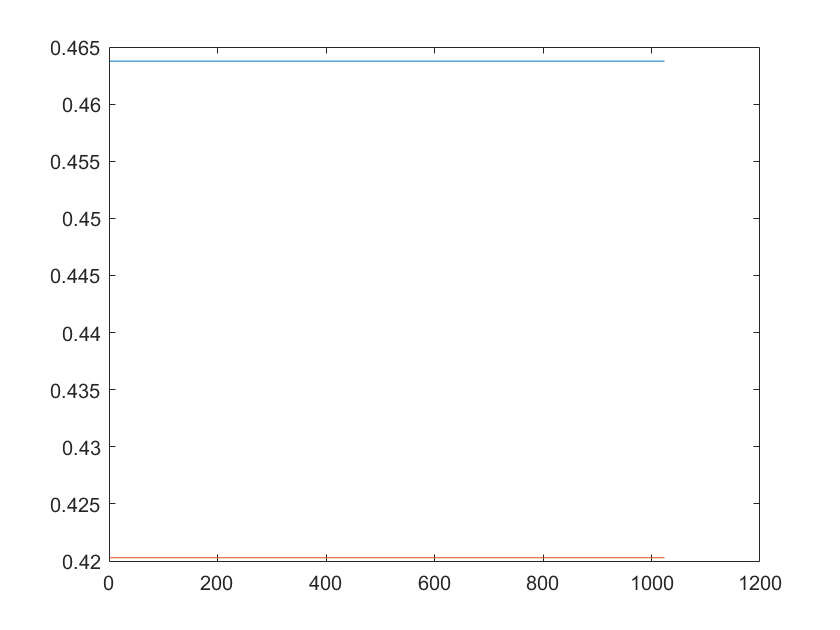

%trial cases 
%plot all the data for the sensor for trial 1
figure(1)
plot(sensor_data(:,:,1))
hold on;
%plot all the data for the thumb roll sensor for trial 2
plot(sensor_data(:,:,2))
hold off;

From these visualizations of the first two trials, we can better understand what the data is showing. Each trial, the person is asked to make different hand positions. So that is why trial 1 and trial 2 have different values for the sensor value. 

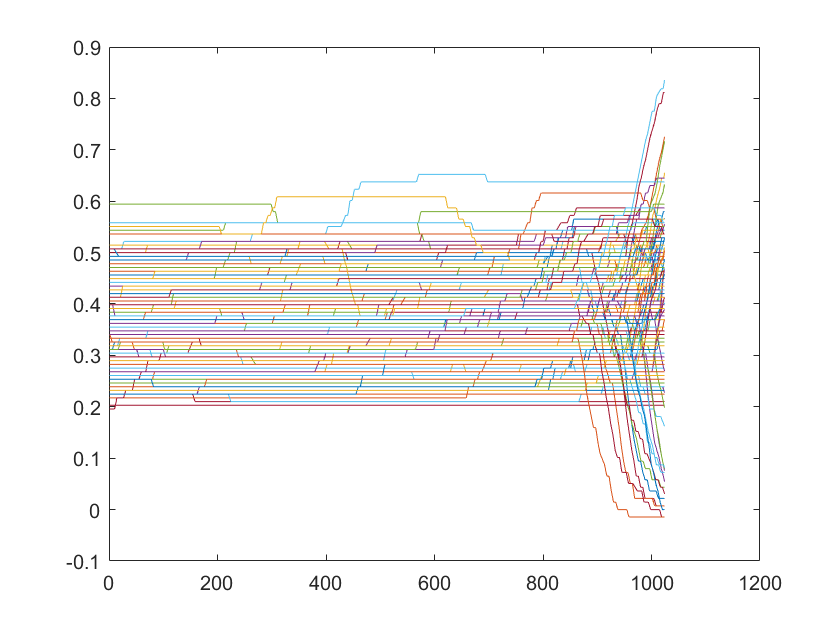

%let's see what happens if we plot the values for the specific 
% sensor for all the trials on the same graph.
figure(2)
for i=1:234
    plot(sensor_data(:,:,i))
    hold on;
end
hold off;

Now, while this seems to make sense, this isn't very useful.

#### Let's plot the glove data for all the sensors for a given trial.

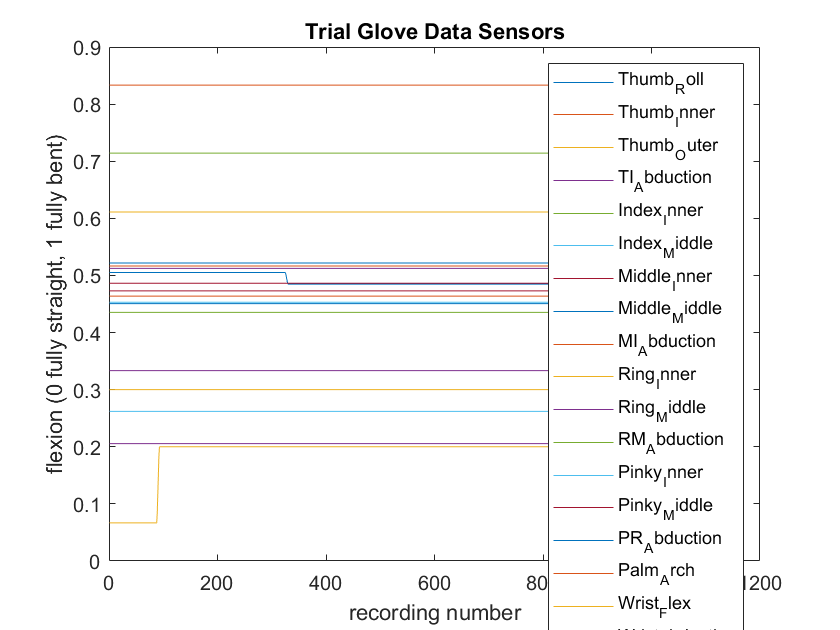

%let's create a variable to denote a particular trial
trial = 1;
trial_data = EEG.glovedata(:,:,trial);
figure(3)
for i=1:18
    plot(trial_data(i,:,:))
    hold on;
end
hold off;

%let's add lables so we can try to understand what is happening
title('Trial Glove Data Sensors')
xlabel('recording number') 
ylabel('flexion (0 fully straight, 1 fully bent)')
legend(EEG.channels_glove)

%let's see what the performed movement was
EEG.movement(:,trial)

ans = categorical
     point 


Clearly this isn't very helpful either. Also notice that the values aren't plotted against time.

#### Let's create a time vector for glove data.

%(1/256)x1000 = interval. So if we want 1024 values w/ said interval, 
% max value is intervalx1024

gtimes = linspace(0,((1/256)*1000)*1024,1024);

#### Let's plot 1 sensor across all trials color coding by movement

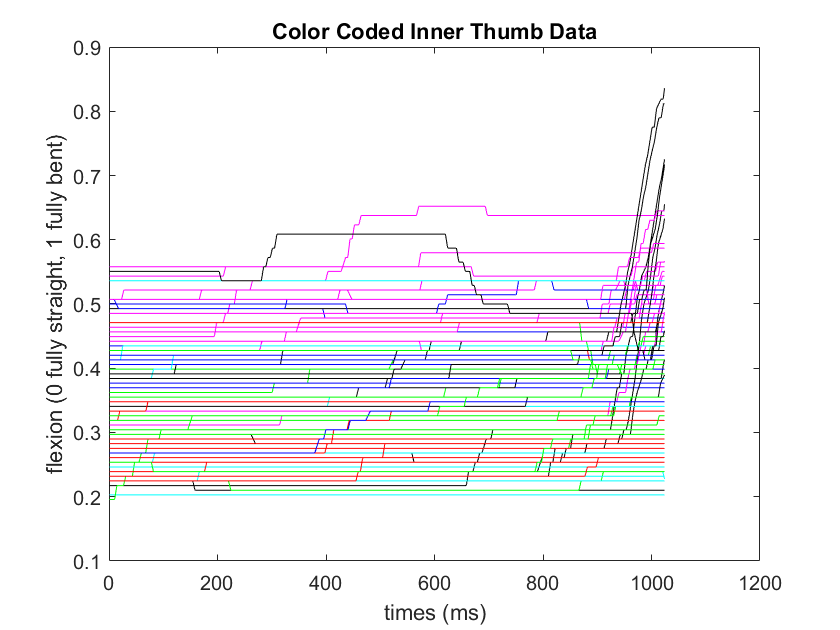

%let's stick with sensor 2
figure(4)
for i=1:234
    switch EEG.movement(:,i)
        case "3 digit"
            color = 'y';
        case "disc"
            color = 'm';
        case "fist"
            color = 'c';
        case "index_flex"
            color = 'r';
        case "middle_flex"
            color = 'g';
        case "point"
            color = 'b';
        case "thumbFlex"
            color = 'k';
        otherwise
            continue
    end
    plot(sensor_data(:,:,i),color)
    hold on;
end
hold off;
title('Color Coded Inner Thumb Data')
xlabel('times (ms)') 
ylabel('flexion (0 fully straight, 1 fully bent)')

This graph is actually beginning to be somewhat useful though not completely. Looking at the graph, I can't make trends right off the bat. But by looking at the color, then seeing what movement it is, I am able to rationalize/see a match between the position and the thumb inner sensor value. Clearly, there are some associations between some of the movements' values too which is good. 

Something I'm curious to look at next is "thresholds." For example, above what threshold value does the index flexion have to be past for it to be the "index flexion" movement?

#### Let's plot index_inner sensor values for all trials that are either "point" or "index flexion" movement.

%reset the sensor variable to index_middle
sensor = 5;
EEG.channels_glove(sensor,:)

ans = 'Index_Inner    '

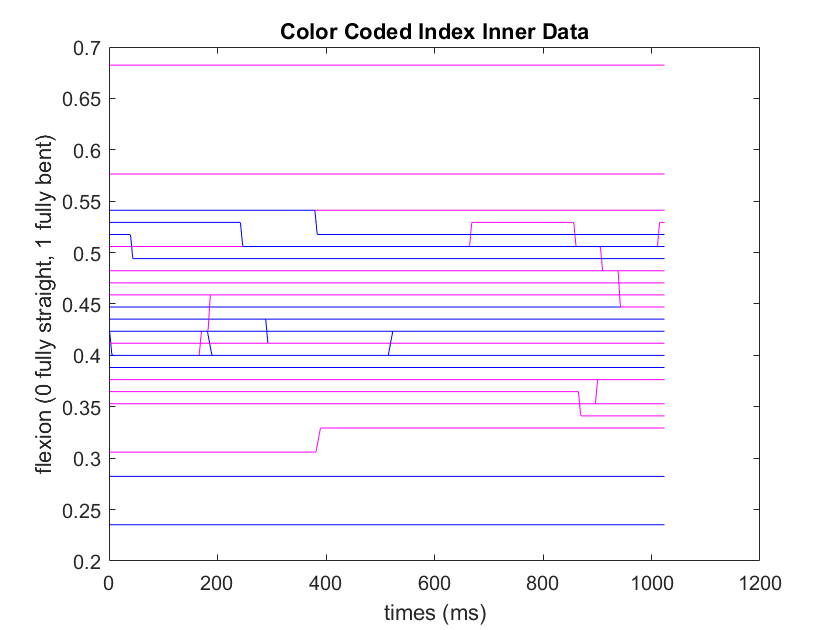


%reset sensor_data with the new sensor
sensor_data = EEG.glovedata(sensor,:,:);

%let's plot point & index flexion color coded
figure(5)
for i=1:234
    switch EEG.movement(:,i)
        case "point"
            color = 'b';
        case "index_flex"
            color = 'm';
        otherwise
            continue
    end
    plot(sensor_data(:,:,i),color)
    hold on;
end
hold off;
title('Color Coded Index Inner Data')
xlabel('times (ms)') 
ylabel('flexion (0 fully straight, 1 fully bent)')

This sort of is understandable but not really...There is a lot of overlap though there is some distinction between the index_flexion being higher up as expected than point. The decrease/increase kind of does match though but still not in each trial.

#### Let's plot thumb_outer sensor values for all trials that are either "thumbExt" or "thumbFlex" movement.

%reset the sensor variable to index_middle
sensor = 3;
EEG.channels_glove(sensor,:)

ans = 'Thumb_Outer    '

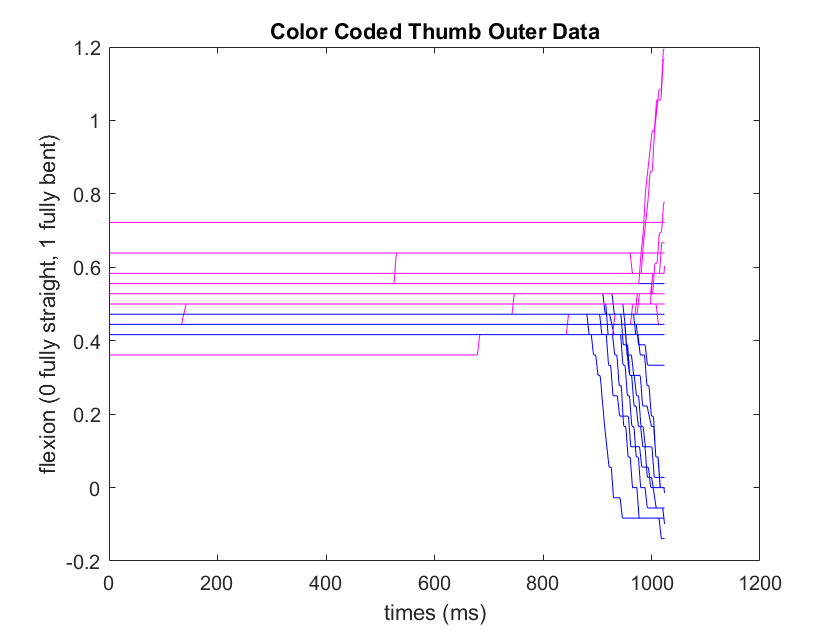


%reset sensor_data with the new sensor
sensor_data = EEG.glovedata(sensor,:,:);

%let's plot point & index flexion color coded
figure(6)
for i=1:234
    switch EEG.movement(:,i)
        case "thumbExt"
            color = 'b';
        case "thumbFlex"
            color = 'm';
        otherwise
            continue
    end
    plot(sensor_data(:,:,i),color)
    hold on;
end
hold off;
title('Color Coded Thumb Outer Data')
xlabel('times (ms)') 
ylabel('flexion (0 fully straight, 1 fully bent)')

This graph is very clear and shows a distinct difference between the two. We can clearly see which one is flexion and which one is extension. Noting that the majority of the "movement' is occuring at the end of the time frame. Let's consider that observations impact in other parts of our analysis too.

#### Let's Now Try Trial 211, with one sensor per finger, and let's see if we can even attempt at guessing what movement it is.

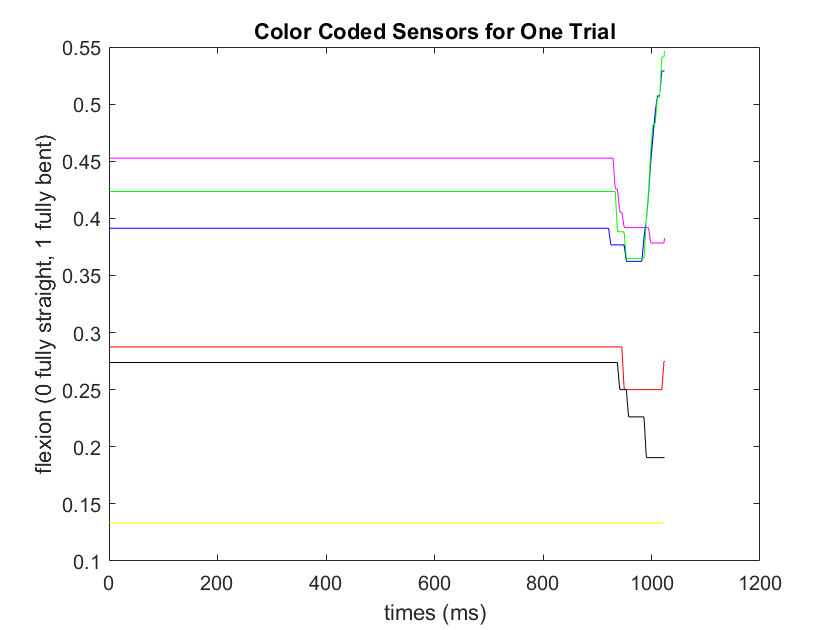

%reset the sensor variable to index_middle
trial = 211;

%reset sensor_data with the new sensor
trial_data = EEG.glovedata(:,:,trial);

%let's plot point & index flexion color coded
figure(7)
for i=1:18
    switch EEG.channels_glove(i,:)
        case 'Thumb_Inner    '
            color = 'b';
        case 'Index_Inner    '
            color = 'g';
        case 'Middle_Inner   '
            color = 'm';
        case 'Ring_Inner     '
            color = 'r';
        case 'Pinky_Inner    '
            color = 'k';
        case 'Wrist_Flex     '
            color = 'y';
        otherwise
            continue
    end
    plot(trial_data(i,:,:),color)
    hold on;
end
hold off;
title('Color Coded Sensors for One Trial')
xlabel('times (ms)') 
ylabel('flexion (0 fully straight, 1 fully bent)')


EEG.movement(:,211)

ans = categorical
     pinch 


#### Let's Now Try Trial 212, with one sensor per finger, and let's see if we can even attempt at guessing what movement it is.

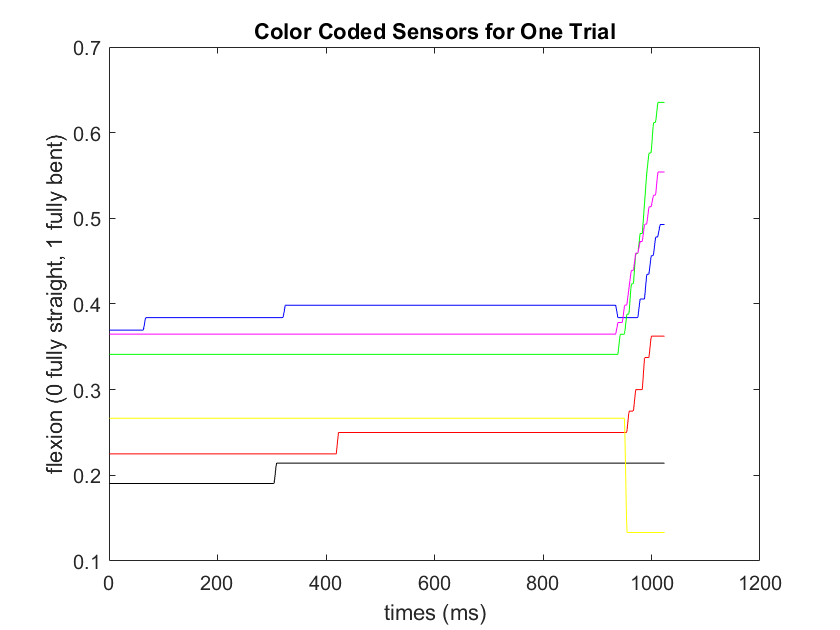

%reset the sensor variable to index_middle
trial = 212;

%reset sensor_data with the new sensor
trial_data = EEG.glovedata(:,:,trial);

%let's plot point & index flexion color coded
figure(8)
for i=1:18
    switch EEG.channels_glove(i,:)
        case 'Thumb_Inner    '
            color = 'b';
        case 'Index_Inner    '
            color = 'g';
        case 'Middle_Inner   '
            color = 'm';
        case 'Ring_Inner     '
            color = 'r';
        case 'Pinky_Inner    '
            color = 'k';
        case 'Wrist_Flex     '
            color = 'y';
        otherwise
            continue
    end
    plot(trial_data(i,:,:),color)
    hold on;
end
hold off;
title('Color Coded Sensors for One Trial')
xlabel('times (ms)') 
ylabel('flexion (0 fully straight, 1 fully bent)')


EEG.movement(:,212)

ans = categorical
     pinch 


Note that in trial 211 and 212, one is able to identify what movement is being conducted to an extent. More so in trial 211 than in trial 212. Notice that even between two trials of the same movement, there are discrepencies based on people's "starting" position. Currently looking at graphs relatively (e.g. the change, is it going up or going down) which varies based on how ur hand starts. 

Once you note the starting point, then some of the misconceptions/changes become more clear on why they may differ.

#### Let's Now Try a Random Trial, with one sensor per finger, and let's see if we can even attempt at guessing what movement it is.

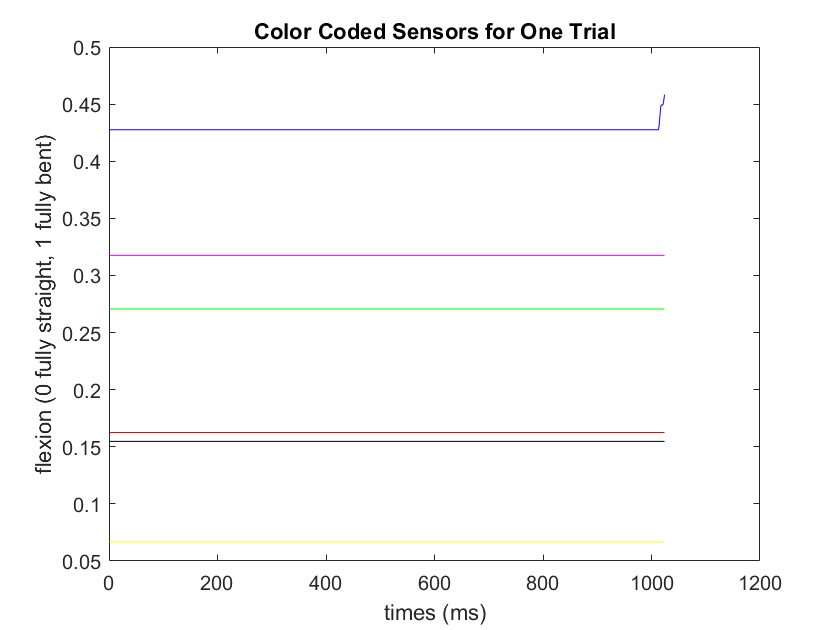

%reset the sensor variable to index_middle
trial = randi([1 234],1,1);

%reset sensor_data with the new sensor
trial_data = EEG.glovedata(:,:,trial);

%let's plot point & index flexion color coded
figure(7)
for i=1:18
    switch EEG.channels_glove(i,:)
        case 'Thumb_Inner    '
            color = 'b';
        case 'Index_Inner    '
            color = 'g';
        case 'Middle_Inner   '
            color = 'm';
        case 'Ring_Inner     '
            color = 'r';
        case 'Pinky_Inner    '
            color = 'k';
        case 'Wrist_Flex     '
            color = 'y';
        otherwise
            continue
    end
    plot(trial_data(i,:,:),color)
    hold on;
end
hold off;
title('Color Coded Sensors for One Trial')
xlabel('times (ms)') 
ylabel('flexion (0 fully straight, 1 fully bent)')


EEG.movement(:,trial)

ans = categorical
     thumbFlex 


#### Let's now plot one trial thumb inner and EMG data to see whether they correspond.

%let's scroll up and change the sensor_data to be sensor 2 - thumb inner

% th_inner_data = EEG.glovedata(sensor,:,200);
% EMG_data = EEG.data(1,:,200);
% 
% figure(6)
% plot(EEG.times,EMG_data)
% hold on;
% plot(gtimes,th_inner_data)
% hold off;

%so this doesn't work as anticipated. I think we need to plot multiple
%trials but reshape the array to have each trial one after the other as a
%column vector (e.g. think back to QEA I)